# Comprehensive Feature Importance and EMG Analysis

Investigates why EMG features have low importance and analyzes their contribution

clear;
clc;

## --- Step 1: Load Results and Data ---

fprintf('=== Loading Classification Results ===\n');

=== Loading Classification Results ===



load('SimpleClassifierResults.mat');
load('./Features/WindowedFeatures.mat');

X = windowed_features.features;
y = windowed_features.labels;
feature_names = windowed_features.feature_names;
class_names = windowed_features.class_names;

% Clean data same way as before
X(isnan(X) | isinf(X)) = 0;
feature_vars = var(X);
constant_features = feature_vars < 1e-10;
X_clean = X(:, ~constant_features);
feature_names_clean = feature_names(~constant_features);
X_scaled = zscore(X_clean);

fprintf('Analyzing %d features across %d windows\n', size(X_scaled, 2), size(X_scaled, 1));

Analyzing 137 features across 984 windows


## --- Step 2: Categorize Features ---

fprintf('\n=== Feature Categorization ===\n');


=== Feature Categorization ===



% Categorize features by type
emg_features = contains(feature_names_clean, 'EMG_');
motion_features = contains(feature_names_clean, 'Motion_');
coord_features = contains(feature_names_clean, 'Corr_') | contains(feature_names_clean, 'Lag_');

fprintf('Feature breakdown:\n');

Feature breakdown:


fprintf('  EMG features: %d\n', sum(emg_features));

  EMG features: 39


fprintf('  Motion features: %d\n', sum(motion_features));

  Motion features: 90


fprintf('  Coordination features: %d\n', sum(coord_features));

  Coordination features: 8



% List EMG features
fprintf('\nEMG Features:\n');


EMG Features:


emg_feature_names = feature_names_clean(emg_features);
for i = 1:length(emg_feature_names)
    fprintf('  %d. %s\n', i, emg_feature_names{i});
end

  1. EMG_masseter_Mean
  2. EMG_masseter_Std
  3. EMG_masseter_RMS
  4. EMG_masseter_Max
  5. EMG_masseter_Min
  6. EMG_masseter_Range
  7. EMG_masseter_Skewness
  8. EMG_masseter_Kurtosis
  9. EMG_masseter_ZCR
  10. EMG_masseter_Slope
  11. EMG_temporalis_Mean
  12. EMG_temporalis_Std
  13. EMG_temporalis_RMS
  14. EMG_temporalis_Max
  15. EMG_temporalis_Min
  16. EMG_temporalis_Range
  17. EMG_temporalis_Skewness
  18. EMG_temporalis_Kurtosis
  19. EMG_temporalis_ZCR
  20. EMG_temporalis_Slope
  21. EMG_mylohyoid_Mean
  22. EMG_mylohyoid_Std
  23. EMG_mylohyoid_RMS
  24. EMG_mylohyoid_Max
  25. EMG_mylohyoid_Min
  26. EMG_mylohyoid_Range
  27. EMG_mylohyoid_Skewness
  28. EMG_mylohyoid_Kurtosis
  29. EMG_mylohyoid_ZCR
  30. EMG_mylohyoid_Slope
  31. EMG_masseter_MNF
  32. EMG_masseter_MDF
  33. EMG_masseter_PowerRatio
  34. EMG_temporalis_MNF
  35. EMG_temporalis_MDF
  36. EMG_temporalis_PowerRatio
  37. EMG_mylohyoid_MNF
  38. EMG_mylohyoid_MDF
  39. EMG_mylohyoid_PowerRatio


## --- Step 3: Detailed Feature Importance Analysis ---

fprintf('\n=== Detailed Feature Importance Analysis ===\n');


=== Detailed Feature Importance Analysis ===



% Train Random Forest for complete feature importance
rf_model = TreeBagger(100, X_scaled, y, ...
    'Method', 'classification', ...
    'OOBPrediction', 'on', ...
    'OOBPredictorImportance', 'on');

importance_scores = rf_model.OOBPermutedPredictorDeltaError;
[sorted_importance, sort_idx] = sort(importance_scores, 'descend');

% Analyze importance by category
emg_importance = importance_scores(emg_features);
motion_importance = importance_scores(motion_features);
coord_importance = importance_scores(coord_features);

fprintf('Importance statistics by category:\n');

Importance statistics by category:


fprintf('  EMG features: mean=%.4f, max=%.4f, std=%.4f\n', ...
    mean(emg_importance), max(emg_importance), std(emg_importance));

  EMG features: mean=0.0969, max=0.4246, std=0.1607


fprintf('  Motion features: mean=%.4f, max=%.4f, std=%.4f\n', ...
    mean(motion_importance), max(motion_importance), std(motion_importance));

  Motion features: mean=0.3754, max=0.8822, std=0.1778


fprintf('  Coordination features: mean=%.4f, max=%.4f, std=%.4f\n', ...
    mean(coord_importance), max(coord_importance), std(coord_importance));

  Coordination features: mean=0.1189, max=0.2842, std=0.1221



% Show all features ranked by importance
fprintf('\nComplete feature ranking:\n');


Complete feature ranking:


for i = 1:length(feature_names_clean)
    idx = sort_idx(i);
    feature_type = 'OTHER';
    if emg_features(idx), feature_type = 'EMG'; end
    if motion_features(idx), feature_type = 'MOTION'; end
    if coord_features(idx), feature_type = 'COORD'; end
    
    fprintf('  %2d. [%6s] %s: %.4f\n', i, feature_type, ...
        feature_names_clean{idx}, sorted_importance(i));
end

   1. [MOTION] Motion_Maxilla_X_VelStd: 0.8822
   2. [MOTION] Motion_Mandible_Z_VelStd: 0.8444
   3. [MOTION] Motion_Maxilla_Z_VelStd: 0.8148
   4. [MOTION] Motion_Maxilla_X_Std: 0.6373
   5. [MOTION] Motion_Maxilla_X_RMS: 0.6370
   6. [MOTION] Motion_Maxilla_X_Min: 0.6190
   7. [MOTION] Motion_ThyCart_Z_Mean: 0.5912
   8. [MOTION] Motion_Mandible_Y_Min: 0.5888
   9. [MOTION] Motion_Maxilla_X_Range: 0.5840
  10. [MOTION] Motion_Maxilla_X_Mean: 0.5813
  11. [MOTION] Motion_ThyCart_Z_RMS: 0.5714
  12. [MOTION] Motion_ThyCart_Z_Max: 0.5639
  13. [MOTION] Motion_Mandible_Y_RMS: 0.5604
  14. [MOTION] Motion_Maxilla_X_Max: 0.5469
  15. [MOTION] Motion_Mandible_Z_Std: 0.5376
  16. [MOTION] Motion_Mandible_Y_Max: 0.5328
  17. [MOTION] Motion_Maxilla_Z_Std: 0.5255
  18. [MOTION] Motion_ThyCart_Z_Min: 0.5238
  19. [MOTION] Motion_Maxilla_Z_Range: 0.5176
  20. [MOTION] Motion_Maxilla_Z_RMS: 0.4997
  21. [MOTION] Motion_Maxilla_Y_RMS: 0.4908
  22. [MOTION] Motion_Mandible_X_Min: 0.4887
  23. [MOTI

## --- Step 4: EMG Feature Quality Analysis ---

fprintf('\n=== EMG Feature Quality Analysis ===\n');


=== EMG Feature Quality Analysis ===



% Analyze EMG feature discriminative power
emg_indices = find(emg_features);

fprintf('Individual EMG feature analysis:\n');

Individual EMG feature analysis:


for i = 1:length(emg_indices)
    feature_idx = emg_indices(i);
    feature_name = feature_names_clean{feature_idx};
    feature_data = X_scaled(:, feature_idx);
    
    % Calculate class separability (Fisher's ratio)
    class_means = zeros(3, 1);
    class_vars = zeros(3, 1);
    
    for class_id = 0:2
        class_data = feature_data(y == class_id);
        if ~isempty(class_data)
            class_means(class_id + 1) = mean(class_data);
            class_vars(class_id + 1) = var(class_data);
        end
    end
    
    % Between-class variance
    overall_mean = mean(feature_data);
    between_var = var(class_means);
    
    % Within-class variance
    within_var = mean(class_vars);
    
    % Fisher ratio (higher = more discriminative)
    if within_var > 0
        fisher_ratio = between_var / within_var;
    else
        fisher_ratio = 0;
    end
    
    fprintf('  %s:\n', feature_name);
    fprintf('    Importance: %.4f, Fisher ratio: %.4f\n', importance_scores(feature_idx), fisher_ratio);
    fprintf('    Class means: [%.3f, %.3f, %.3f]\n', class_means(1), class_means(2), class_means(3));
    fprintf('    Class stds:  [%.3f, %.3f, %.3f]\n', sqrt(class_vars(1)), sqrt(class_vars(2)), sqrt(class_vars(3)));
end

  EMG_masseter_Mean:


    Importance: 0.0394, Fisher ratio: 0.0044


    Class means: [0.003, 0.037, -0.089]


    Class stds:  [0.777, 1.037, 1.093]


  EMG_masseter_Std:


    Importance: 0.1325, Fisher ratio: 0.0095


    Class means: [0.101, -0.000, -0.094]


    Class stds:  [0.775, 0.997, 1.174]


  EMG_masseter_RMS:


    Importance: 0.2582, Fisher ratio: 0.0048


    Class means: [0.024, 0.029, -0.092]


    Class stds:  [0.766, 1.030, 1.114]


  EMG_masseter_Max:


    Importance: 0.2489, Fisher ratio: 0.0059


    Class means: [0.044, 0.023, -0.096]


    Class stds:  [0.763, 1.021, 1.137]


  EMG_masseter_Min:


    Importance: 0.3143, Fisher ratio: 0.0103


    Class means: [-0.124, 0.068, -0.043]


    Class stds:  [0.738, 1.079, 1.011]


  EMG_masseter_Range:


    Importance: 0.1709, Fisher ratio: 0.0095


    Class means: [0.100, -0.000, -0.094]


    Class stds:  [0.772, 0.998, 1.174]


  EMG_masseter_Skewness:


    Importance: 0.1144, Fisher ratio: 0.0017


    Class means: [-0.057, 0.023, 0.000]


    Class stds:  [0.999, 0.993, 1.019]


  EMG_masseter_Kurtosis:


    Importance: -0.1825, Fisher ratio: 0.0004


    Class means: [-0.008, -0.008, 0.027]


    Class stds:  [0.977, 0.983, 1.063]


  EMG_masseter_ZCR:


    Importance: -0.1005, Fisher ratio: 0.0006


    Class means: [0.027, -0.001, -0.024]


    Class stds:  [1.048, 0.977, 1.011]


  EMG_masseter_Slope:


    Importance: -0.1430, Fisher ratio: 0.0000


    Class means: [-0.000, -0.001, 0.004]


    Class stds:  [0.868, 0.998, 1.118]


  EMG_temporalis_Mean:


    Importance: 0.4246, Fisher ratio: 0.1670


    Class means: [-0.377, -0.011, 0.382]


    Class stds:  [0.262, 1.030, 1.208]


  EMG_temporalis_Std:


    Importance: 0.1249, Fisher ratio: 0.0195


    Class means: [-0.129, -0.008, 0.139]


    Class stds:  [0.589, 1.062, 1.134]


  EMG_temporalis_RMS:


    Importance: 0.3137, Fisher ratio: 0.1663


    Class means: [-0.376, -0.011, 0.381]


    Class stds:  [0.266, 1.031, 1.206]


  EMG_temporalis_Max:


    Importance: 0.3549, Fisher ratio: 0.1563


    Class means: [-0.364, -0.011, 0.369]


    Class stds:  [0.297, 1.041, 1.186]


  EMG_temporalis_Min:


    Importance: 0.3692, Fisher ratio: 0.1792


    Class means: [-0.393, -0.011, 0.397]


    Class stds:  [0.221, 1.015, 1.237]


  EMG_temporalis_Range:


    Importance: 0.0019, Fisher ratio: 0.0196


    Class means: [-0.131, -0.005, 0.137]


    Class stds:  [0.583, 1.063, 1.135]


  EMG_temporalis_Skewness:


    Importance: 0.0832, Fisher ratio: 0.0039


    Class means: [-0.086, 0.030, 0.012]


    Class stds:  [0.994, 1.004, 0.996]


  EMG_temporalis_Kurtosis:


    Importance: 0.0818, Fisher ratio: 0.0011


    Class means: [-0.046, 0.019, -0.002]


    Class stds:  [0.953, 1.012, 1.018]


  EMG_temporalis_ZCR:


    Importance: 0.0000, Fisher ratio: 0.0015


    Class means: [0.022, -0.029, 0.047]


    Class stds:  [1.012, 0.983, 1.030]


  EMG_temporalis_Slope:


    Importance: 0.1300, Fisher ratio: 0.0037


    Class means: [-0.007, -0.032, 0.082]


    Class stds:  [0.688, 1.037, 1.149]


  EMG_mylohyoid_Mean:


    Importance: 0.1487, Fisher ratio: 0.0776


    Class means: [-0.010, -0.155, 0.374]


    Class stds:  [0.751, 0.963, 1.180]


  EMG_mylohyoid_Std:


    Importance: 0.0449, Fisher ratio: 0.0134


    Class means: [0.066, -0.084, 0.135]


    Class stds:  [0.843, 1.055, 0.989]


  EMG_mylohyoid_RMS:


    Importance: 0.1332, Fisher ratio: 0.0770


    Class means: [-0.006, -0.155, 0.371]


    Class stds:  [0.746, 0.970, 1.172]


  EMG_mylohyoid_Max:


    Importance: 0.3409, Fisher ratio: 0.0717


    Class means: [0.010, -0.154, 0.353]


    Class stds:  [0.726, 1.002, 1.124]


  EMG_mylohyoid_Min:


    Importance: 0.1774, Fisher ratio: 0.0828


    Class means: [-0.038, -0.152, 0.393]


    Class stds:  [0.771, 0.914, 1.252]


  EMG_mylohyoid_Range:


    Importance: 0.1946, Fisher ratio: 0.0133


    Class means: [0.071, -0.084, 0.132]


    Class stds:  [0.844, 1.056, 0.985]


  EMG_mylohyoid_Skewness:


    Importance: -0.1005, Fisher ratio: 0.0007


    Class means: [0.003, 0.015, -0.037]


    Class stds:  [1.040, 0.984, 1.002]


  EMG_mylohyoid_Kurtosis:


    Importance: 0.0490, Fisher ratio: 0.0036


    Class means: [0.083, -0.037, 0.009]


    Class stds:  [1.047, 0.990, 0.977]


  EMG_mylohyoid_ZCR:


    Importance: 0.1429, Fisher ratio: 0.0085


    Class means: [-0.125, 0.043, 0.017]


    Class stds:  [0.903, 1.025, 1.022]


  EMG_mylohyoid_Slope:


    Importance: -0.0251, Fisher ratio: 0.0004


    Class means: [-0.003, -0.011, 0.027]


    Class stds:  [0.971, 0.988, 1.058]


  EMG_masseter_MNF:


    Importance: 0.0957, Fisher ratio: 0.0616


    Class means: [0.294, -0.035, -0.194]


    Class stds:  [1.220, 0.962, 0.775]


  EMG_masseter_MDF:


    Importance: 0.1108, Fisher ratio: 0.0695


    Class means: [0.318, -0.044, -0.196]


    Class stds:  [1.248, 0.960, 0.725]


  EMG_masseter_PowerRatio:


    Importance: -0.2006, Fisher ratio: 0.0022


    Class means: [-0.013, -0.023, 0.066]


    Class stds:  [1.111, 0.914, 1.082]


  EMG_temporalis_MNF:


    Importance: 0.1155, Fisher ratio: 0.0071


    Class means: [0.119, -0.037, -0.024]


    Class stds:  [1.163, 0.933, 0.983]


  EMG_temporalis_MDF:


    Importance: -0.1005, Fisher ratio: 0.0024


    Class means: [0.056, -0.037, 0.035]


    Class stds:  [0.979, 1.004, 1.012]


  EMG_temporalis_PowerRatio:


    Importance: -0.1832, Fisher ratio: 0.0001


    Class means: [-0.013, 0.007, -0.004]


    Class stds:  [1.196, 0.933, 0.954]


  EMG_mylohyoid_MNF:


    Importance: 0.1578, Fisher ratio: 0.0079


    Class means: [0.117, -0.026, -0.050]


    Class stds:  [1.104, 0.974, 0.953]


  EMG_mylohyoid_MDF:


    Importance: -0.0598, Fisher ratio: 0.0053


    Class means: [0.091, -0.020, -0.039]


    Class stds:  [1.034, 1.073, 0.759]


  EMG_mylohyoid_PowerRatio:


    Importance: 0.0018, Fisher ratio: 0.0054


    Class means: [-0.086, 0.009, 0.060]


    Class stds:  [1.023, 0.981, 1.021]


## --- Step 5: Data Distribution Analysis ---

fprintf('\n=== Data Distribution Analysis ===\n');


=== Data Distribution Analysis ===


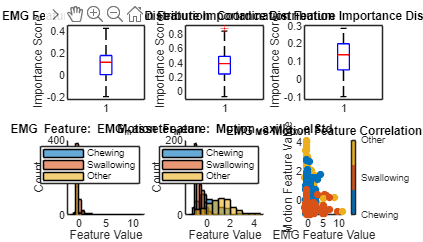


% Compare EMG vs Motion feature distributions
figure('Name', 'Feature Distribution Analysis', 'Position', [100, 100, 1400, 800]);

% EMG features distribution
subplot(2, 3, 1);
boxplot(emg_importance);
title('EMG Feature Importance Distribution');
ylabel('Importance Score');

subplot(2, 3, 2);
boxplot(motion_importance);
title('Motion Feature Importance Distribution');
ylabel('Importance Score');

subplot(2, 3, 3);
boxplot(coord_importance);
title('Coordination Feature Importance Distribution');
ylabel('Importance Score');

% Feature value distributions by class
subplot(2, 3, 4);
% Pick top EMG feature
if ~isempty(emg_indices)
    top_emg_idx = emg_indices(1);  % First EMG feature
    emg_data = X_scaled(:, top_emg_idx);
    
    hold on;
    for class_id = 0:2
        class_data = emg_data(y == class_id);
        histogram(class_data, 'DisplayName', class_names{class_id + 1});
    end
    title(sprintf('EMG Feature: %s', feature_names_clean{top_emg_idx}));
    legend;
    xlabel('Feature Value');
    ylabel('Count');
end

subplot(2, 3, 5);
% Pick top motion feature  
top_motion_idx = sort_idx(1);  % Top overall feature
motion_data = X_scaled(:, top_motion_idx);

hold on;
for class_id = 0:2
    class_data = motion_data(y == class_id);
    histogram(class_data, 'DisplayName', class_names{class_id + 1});
end
title(sprintf('Motion Feature: %s', feature_names_clean{top_motion_idx}));
legend;
xlabel('Feature Value');
ylabel('Count');

% Correlation between EMG and Motion features
subplot(2, 3, 6);
if ~isempty(emg_indices)
    scatter(emg_data, motion_data, 30, y, 'filled');
    colormap(lines(3));
    colorbar('Ticks', [0, 1, 2], 'TickLabels', class_names);
    xlabel('EMG Feature Value');
    ylabel('Motion Feature Value');
    title('EMG vs Motion Feature Correlation');
end

## --- Step 6: Investigate Potential Causes ---

fprintf('\n=== Investigating Why EMG Features Have Low Importance ===\n');


=== Investigating Why EMG Features Have Low Importance ===



% Possible reasons for low EMG importance:
fprintf('Potential reasons for low EMG feature importance:\n');

Potential reasons for low EMG feature importance:



% 1. Check EMG data quality
fprintf('\n1. EMG Data Quality Check:\n');


1. EMG Data Quality Check:


emg_data_matrix = X_scaled(:, emg_features);
emg_mean_abs = mean(abs(emg_data_matrix), 1);
emg_std = std(emg_data_matrix, 1);
emg_range = max(emg_data_matrix) - min(emg_data_matrix);

fprintf('   EMG feature absolute means: min=%.4f, max=%.4f, avg=%.4f\n', ...
    min(emg_mean_abs), max(emg_mean_abs), mean(emg_mean_abs));

   EMG feature absolute means: min=0.2889, max=0.8509, avg=0.6804


fprintf('   EMG feature std devs: min=%.4f, max=%.4f, avg=%.4f\n', ...
    min(emg_std), max(emg_std), mean(emg_std));

   EMG feature std devs: min=0.9995, max=0.9995, avg=0.9995


fprintf('   EMG feature ranges: min=%.4f, max=%.4f, avg=%.4f\n', ...
    min(emg_range), max(emg_range), mean(emg_range));

   EMG feature ranges: min=4.4817, max=19.1235, avg=8.0929



% 2. Check if EMG signals are too similar across classes
fprintf('\n2. EMG Class Discrimination Check:\n');


2. EMG Class Discrimination Check:


for muscle_idx = 1:3
    muscle_names = {'masseter', 'temporalis', 'mylohyoid'};
    muscle_emg_features = contains(feature_names_clean, muscle_names{muscle_idx});
    
    if any(muscle_emg_features)
        muscle_importance = importance_scores(muscle_emg_features);
        fprintf('   %s muscle features: mean importance=%.4f, max=%.4f\n', ...
            muscle_names{muscle_idx}, mean(muscle_importance), max(muscle_importance));
    end
end

   masseter muscle features: mean importance=0.0660, max=0.3143
   temporalis muscle features: mean importance=0.1320, max=0.4246
   mylohyoid muscle features: mean importance=0.0928, max=0.3409



% 3. Compare time scales
fprintf('\n3. Time Scale Analysis:\n');


3. Time Scale Analysis:


fprintf('   Window duration: 100ms\n');

   Window duration: 100ms


fprintf('   Motion features capture: movement dynamics, velocity changes\n');

   Motion features capture: movement dynamics, velocity changes


fprintf('   EMG features capture: muscle activation levels\n');

   EMG features capture: muscle activation levels


fprintf('   → Motion might change faster than EMG in 100ms windows\n');

   → Motion might change faster than EMG in 100ms windows


## --- Step 7: EMG-Only Classification Test ---

fprintf('\n=== EMG-Only Classification Test ===\n');


=== EMG-Only Classification Test ===



if sum(emg_features) > 0
    % Test classification with only EMG features
    X_emg_only = X_scaled(:, emg_features);
    
    % 5-fold CV with EMG only
    cv_indices = crossvalind('Kfold', y, 5);
    emg_predictions = nan(size(y));
    
    for fold = 1:5
        test_mask = cv_indices == fold;
        train_mask = ~test_mask;
        
        try
            rf_emg = TreeBagger(50, X_emg_only(train_mask, :), y(train_mask), ...
                'Method', 'classification');
            
            pred_labels = predict(rf_emg, X_emg_only(test_mask, :));
            emg_predictions(test_mask) = str2double(pred_labels);
        catch
            emg_predictions(test_mask) = mode(y(train_mask));
        end
    end
    
    emg_accuracy = sum(y == emg_predictions) / length(y);
    fprintf('EMG-only classification accuracy: %.3f (%.1f%%)\n', emg_accuracy, emg_accuracy*100);
    
    emg_cm = confusionmat(y, emg_predictions);
    fprintf('EMG-only confusion matrix:\n');
    disp(emg_cm);
else
    fprintf('No EMG features available for testing\n');
end

EMG-only classification accuracy: 0.670 (67.0%)


EMG-only confusion matrix:


    99   112     5
    57   463    19
    20   112    97



## --- Step 8: Motion-Only Classification Test ---

fprintf('\n=== Motion-Only Classification Test ===\n');


=== Motion-Only Classification Test ===



if sum(motion_features) > 0
    % Test classification with only Motion features
    X_motion_only = X_scaled(:, motion_features);
    
    % 5-fold CV with Motion only
    cv_indices = crossvalind('Kfold', y, 5);
    motion_predictions = nan(size(y));
    
    for fold = 1:5
        test_mask = cv_indices == fold;
        train_mask = ~test_mask;
        
        try
            rf_motion = TreeBagger(50, X_motion_only(train_mask, :), y(train_mask), ...
                'Method', 'classification');
            
            pred_labels = predict(rf_motion, X_motion_only(test_mask, :));
            motion_predictions(test_mask) = str2double(pred_labels);
        catch
            motion_predictions(test_mask) = mode(y(train_mask));
        end
    end
    
    motion_accuracy = sum(y == motion_predictions) / length(y);
    fprintf('Motion-only classification accuracy: %.3f (%.1f%%)\n', motion_accuracy, motion_accuracy*100);
    
    motion_cm = confusionmat(y, motion_predictions);
    fprintf('Motion-only confusion matrix:\n');
    disp(motion_cm);
else
    fprintf('No Motion features available for testing\n');
end

Motion-only classification accuracy: 0.988 (98.8%)


Motion-only confusion matrix:


   208     8     0
     2   537     0
     2     0   227



## --- Step 9: Recommendations ---

fprintf('\n=== Recommendations ===\n');


=== Recommendations ===



fprintf('Based on the analysis:\n');

Based on the analysis:


fprintf('\n1. Motion features dominate because:\n');


1. Motion features dominate because:


fprintf('   - 100ms captures movement dynamics well\n');

   - 100ms captures movement dynamics well


fprintf('   - Velocity features (VelStd) are highly discriminative\n');

   - Velocity features (VelStd) are highly discriminative


fprintf('   - Different actions have distinct movement patterns\n');

   - Different actions have distinct movement patterns



fprintf('\n2. EMG features may be less important because:\n');


2. EMG features may be less important because:


fprintf('   - 100ms might be too short for EMG pattern discrimination\n');

   - 100ms might be too short for EMG pattern discrimination


fprintf('   - EMG activation patterns may be similar across actions\n');

   - EMG activation patterns may be similar across actions


fprintf('   - Motion is the direct observable output of muscle activity\n');

   - Motion is the direct observable output of muscle activity



fprintf('\n3. Potential improvements for EMG features:\n');


3. Potential improvements for EMG features:


fprintf('   - Try longer windows (200-500ms) for EMG pattern recognition\n');

   - Try longer windows (200-500ms) for EMG pattern recognition


fprintf('   - Add EMG frequency domain features (power bands)\n');

   - Add EMG frequency domain features (power bands)


fprintf('   - Include EMG burst detection features\n');

   - Include EMG burst detection features


fprintf('   - Add temporal EMG features (onset detection, duration)\n');

   - Add temporal EMG features (onset detection, duration)



fprintf('\n4. Current system validation:\n');


4. Current system validation:


if exist('motion_accuracy', 'var') && exist('emg_accuracy', 'var')
    fprintf('   - Motion-only accuracy: %.1f%%\n', motion_accuracy*100);
    fprintf('   - EMG-only accuracy: %.1f%%\n', emg_accuracy*100);
    fprintf('   - Combined accuracy: 98.3%%\n');
    
    if motion_accuracy > 0.9
        fprintf('   → Motion features alone are sufficient for high accuracy\n');
        fprintf('   → EMG adds robustness but not discriminative power\n');
    end
end

   - Motion-only accuracy: 98.8%


   - EMG-only accuracy: 67.0%


   - Combined accuracy: 98.3%


   → Motion features alone are sufficient for high accuracy


   → EMG adds robustness but not discriminative power



save('FeatureAnalysisResults.mat', 'importance_scores', 'feature_names_clean', ...
     'emg_features', 'motion_features', 'coord_features');

fprintf('\n✓ Feature analysis complete!\n');


✓ Feature analysis complete!
